# DHN RL Control Script - generic example

This Script is is the control script for the Simulink model "DHNV812163_genericExample".

Created by Ditlev Leth for the Master Thesis " Development and implemtation of data driven control for district heating power plant to provide grid support" at The Danish Technical University due 01/06-2023. The code is inspired by the Matlab Example "Water Distribution System Schedueling Using Reinforcement Learning".

The below is a generic example detailing how to train an RL agent for a specific scenario.

## Defining constants

clc;
clear;
%cd 'C:\Users\....'
%please edit you path above.

h_max = 80000; %tank size in kWh. Please note altering this also require manual alteration of the "limit" block in the simulink model.
P_h = 0.22; % normalised price for straw pr kWh.
num_days = 365; %number of days to generate data for
SampleTime = 1; %sampletime in model (hourly)
mdl = "DHNV812163_genericExample"; %specific model
T = readtable("HeatDemandData.xlsx"); %datafile for heat data

heatConsumption = T{:,24}; %extracting summarised data from 10 houses
heatMax = max(heatConsumption); %finding max value for normlization.
t = 0:(num_days*24)-1; %creating t array for timeseries.

%creating heat demand time series.
heatDemand = timeseries(heatConsumption,t);
heatDemand.Name = "Heat Demand";
heatDemand.TimeInfo.Units = 'hours';

%creating hourAhead matrix
T0 = readtable("ElSpot2020DK2.csv");
T1 = readtable("ElSpot2021DK2.CSV");
T0 = table2array(T0);
T1 = table2array(T1);

%Applying MVA to the price signal
MeanT0 = movmean(T0(1:2050),10); %2020 dataset
MeanT1 = movmean(T1(1:2050)-180,10); %2021 dataset
m0 = max(MeanT0);
m1 = max(MeanT1);
maxVal = max(m0, m1); %finding max value of the dataset for normalisation
Data2020 = MeanT0/maxVal;
Data2021 = MeanT1/maxVal;

%Set data set for training
HourAhead = Data2020;

%Creating timeseries aray for PLA featuers.
t = 1:2050;

hourAhead = timeseries(HourAhead,t);
hourAhead.Name = "Hour Ahead Price";
hourAhead.TimeInfo.Units = 'hours';

%Creating individual PLA features.
TP1 = HourAhead(2:end);
TP2 = HourAhead(3:end);
TP3 = HourAhead(4:end);
TP4 = HourAhead(5:end);
TP5 = HourAhead(6:end);
TP6 = HourAhead(7:end);
TP7 = HourAhead(8:end);
TP8 = HourAhead(9:end);
TP9 = HourAhead(10:end);
TP10 = HourAhead(11:end);
TP11 = HourAhead(12:end);
TP12 = HourAhead(13:end);
TP13 = HourAhead(14:end);
TP14 = HourAhead(15:end);
TP15 = HourAhead(16:end);
TP16 = HourAhead(17:end);
TP17 = HourAhead(18:end);
TP18 = HourAhead(19:end);
TP19 = HourAhead(20:end);
TP20 = HourAhead(21:end);
TP21 = HourAhead(22:end);
TP22 = HourAhead(23:end);
TP23 = HourAhead(24:end);

t = 1:2050-1;
TS1 = timeseries(TP1,t);
TS1.TimeInfo.Units = 'hours';

t = 1:2050-2;
TS2 = timeseries(TP2,t);
TS2.TimeInfo.Units = 'hours';

t = 1:2050-3;
TS3 = timeseries(TP3,t);
TS3.TimeInfo.Units = 'hours';

t = 1:2050-4;
TS4 = timeseries(TP4,t);
TS4.TimeInfo.Units = 'hours';

t = 1:2050-5;
TS5 = timeseries(TP5,t);
TS5.TimeInfo.Units = 'hours';

t = 1:2050-6;
TS6 = timeseries(TP6,t);
TS6.TimeInfo.Units = 'hours';

t = 1:2050-7;
TS7 = timeseries(TP7,t);
TS7.TimeInfo.Units = 'hours';

t = 1:2050-8;
TS8 = timeseries(TP8,t);
TS8.TimeInfo.Units = 'hours';

t = 1:2050-9;
TS9 = timeseries(TP9,t);
TS9.TimeInfo.Units = 'hours';

t = 1:2050-10;
TS10 = timeseries(TP10,t);
TS10.TimeInfo.Units = 'hours';

t = 1:2050-11;
TS11 = timeseries(TP11,t);
TS11.TimeInfo.Units = 'hours';

t = 1:2050-12;
TS12 = timeseries(TP12,t);
TS12.TimeInfo.Units = 'hours';

t = 1:2050-13;
TS13 = timeseries(TP13,t);
TS13.TimeInfo.Units = 'hours';

t = 1:2050-14;
TS14 = timeseries(TP14,t);
TS14.TimeInfo.Units = 'hours';

t = 1:2050-15;
TS15 = timeseries(TP15,t);
TS15.TimeInfo.Units = 'hours';

t = 1:2050-16;
TS16 = timeseries(TP16,t);
TS16.TimeInfo.Units = 'hours';

t = 1:2050-17;
TS17 = timeseries(TP17,t);
TS17.TimeInfo.Units = 'hours';

t = 1:2050-18;
TS18 = timeseries(TP18,t);
TS18.TimeInfo.Units = 'hours';

t = 1:2050-19;
TS19 = timeseries(TP19,t);
TS19.TimeInfo.Units = 'hours';

t = 1:2050-20;
TS20 = timeseries(TP20,t);
TS20.TimeInfo.Units = 'hours';

t = 1:2050-21;
TS21 = timeseries(TP21,t);
TS21.TimeInfo.Units = 'hours';

t = 1:2050-22;
TS22 = timeseries(TP22,t);
TS22.TimeInfo.Units = 'hours';

t = 1:2050-23;
TS23 = timeseries(TP23,t);
TS23.TimeInfo.Units = 'hours';

open_system(mdl)

## Actions and observations

%Action info is the actions that can be taken. The following has been
%specified:
% 0 0= everything off
% 1 0= electric heating on
% 0 1 = strawboiler on
% 1 1 = both on

%For use with discerete action space and simple control:
actInfo = rlFiniteSetSpec({[0 0],[1 0],[0 1],[1 1]});

%For use with advanced discrete control. To generate output vector faster,
% [x y]
%x = electric setpoint:
% 0 = 0 MW
% 1 = 600
% 2 = 1200
% 3 = 1800
% 4 = 2400
%y = straw setpoint:
% 0 = 0 MW
% 1 = 1200
% 2 = 2400
% 3 = 3600
% 4 = 4800
%actInfo = rlFiniteSetSpec({[0 0],[1 0],[2 0],[3 0],[4 0],[0 1],[1 1],[2 1],[3 1],[4 1],[0 2],[1 2],[2 2],[3 2],[4 2],[0 3],[1 3],[2 3],[3 3],[4 3],[0 4],[1 4],[2 4],[3 4],[4 4]})

%Define total number of observations. This number varies depending on the
%case
obsInfo = rlNumericSpec([28 1]);

%create enviornment interface
env = rlSimulinkEnv(mdl,mdl+"/RL Agent",obsInfo, actInfo);

## Create DNN


layers = [
        featureInputLayer(obsInfo.Dimension(1),"Name","state","Normalization","none")
        fullyConnectedLayer(32,"Name","fc_1")
        reluLayer("Name","relu_body1")
        fullyConnectedLayer(32,"Name","fc_2")
        reluLayer("Name","relu_body2")
        fullyConnectedLayer(32,"Name","fc_3")
        reluLayer("Name","relu_body3")
        fullyConnectedLayer(numel(actInfo.Elements),"Name","output")];

dnn = dlnetwork(layers);

%creating critic
criticOpts = rlOptimizerOptions('learnRate',0.001,'GradientThreshold',1);
critic = rlVectorQValueFunction(dnn,obsInfo,actInfo);


## Create DQN Agent

%Setting hyperparameters for the DQN agent. These do not change between agents.
opt = rlDQNAgentOptions('SampleTime',SampleTime);
opt.SequenceLength = 1;
opt.DiscountFactor = 0.995;
opt.ExperienceBufferLength = 1e6;
opt.EpsilonGreedyExploration.EpsilonDecay = 1e-5;
opt.EpsilonGreedyExploration.EpsilonMin = .02;
opt.CriticOptimizerOptions = criticOpts;
opt.NumStepsToLookAhead = 1;

%create agent
agent = rlDQNAgent(critic,opt);



## Train agent

%setting training options. This are configured as max 2000 steps pr
%episodes, which was in practice what was run in every episode as
%end-of-training signals are defined in the simulink model. Max episodes is
%primarily set as an upper bound as in practice the model was run for 2-300
%episodes.


trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 5000,...
    'MaxStepsPerEpisode', 2000, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'StopTrainingCriteria','EpisodeCount',...
    'StopTrainingValue',5000,...
    'ScoreAveragingWindowLength',100);

%Run training. Note that depending on system resources, from the command is
%run it can take 2-3 minutes until the RL training windows is fully loaded.
%Furthermore it can be a few minutes until the first datapoint is visible
%in the generated plot.
%Training can take anywhere from 1 to 4 hours depending on system
%resources.
trainingStats = train(agent,env,trainOpts)

trainingStats =   rlTrainingResult with properties:

       EpisodeIndex: [4×1 double]
      EpisodeReward: [4×1 double]
       EpisodeSteps: [4×1 double]
      AverageReward: [4×1 double]
    TotalAgentSteps: [4×1 double]
       AverageSteps: [4×1 double]
          EpisodeQ0: [4×1 double]
     SimulationInfo: [4×1 Simulink.SimulationOutput]
    TrainingOptions: [1×1 rl.option.rlTrainingOptions]


## Validation - running a simulation    

%Load command for loading of pre-trained agent.
load("agent0_NoStartUpPenalty_MVASignal.mat","agent")
%load("agent1_WithStartUpPenalty_MVASignal.mat","agent");


%run simulation using the existing enviornment (2020 data) for quick
%verification.
simout = sim(agent, env);

   

## Testing

The output is structured this way:

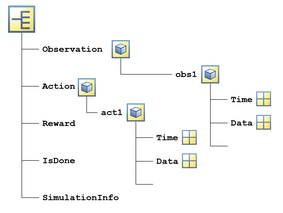

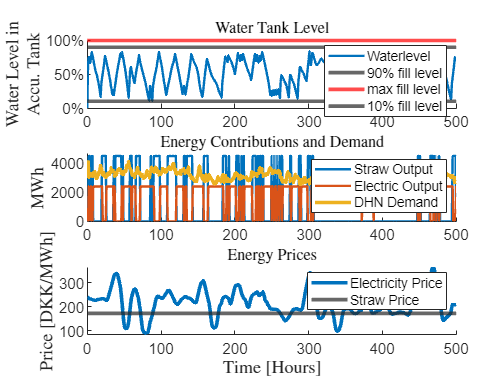

%First - checking the data input. For this we use the observation data.
obs = simout.Observation.obs1.Data;
%Change array into mat:
obsmat = squeeze(obs);
obsmat = obsmat';
%Extract time array
t = simout.Observation.obs1.Time;

%extract observations
demand = obsmat(:,2);
waterLevel = obsmat(:,4);
cost = obsmat(:,3);
hourahead = obsmat(:,1);

%extract actions
act = simout.Action.act1.Data;
actmat = squeeze(act);
%actmat start from t=1 and not t =0, so one datapoint is added.
actmat = actmat';
actmat = [0 0 ; actmat];

%Set standard plot options
set(0,'DefaultTextInterpreter','latex');
DefFontSize = 15; % for a column in paper use 20
set(0,'DefaultAxesFontSize',DefFontSize);
set(0,'DefaultLineLineWidth', 1);

%plot training plot for evaluation
gcf = figure();

%Watertank level
subplot(3,1,1)
hold on;
plot(t,waterLevel*100, 'LineWidth',2)
ytickformat('percentage')
yline(90,'LineWidth',3) %90% fill level
yline(100,'LineWidth',3,'Color', [1,0,0]) %max fill level
yline(10,'LineWidth',3)% 10% fill level
legend('Waterlevel','90% fill level', 'max fill level', '10% fill level','location','northeast')
title({'Water Tank Level'})
%xlabel({'Time [Hours]'}, 'FontSize',DefFontSize,'Interpreter','latex');
ylabel({'Water Level in','Accu. Tank'}, 'FontSize',DefFontSize,'Interpreter','latex');
axis([0 500 -inf inf]);

%production and demand
subplot(3,1,2)
hold on;
plot(actmat(:,2)*4500,'LineWidth',2) %scale according to production from normalised values. This should be changed for multilevel control
plot(actmat(:,1)*2400,'LineWidth',2) %scale according to production from normalised values. This should be changed for multilevel control
plot(heatConsumption*200,'LineWidth',3) %*200 to scale the demand according to the simulink model
legend('Straw Output','Electric Output','DHN Demand','location','northeast')
axis([0 500 -inf inf]);
title('Energy Contributions and Demand')
%xlabel({'Time [Hours]'}, 'FontSize',DefFontSize,'Interpreter','latex');
ylabel({'MWh'}, 'FontSize',DefFontSize,'Interpreter','latex');

%Price signals
subplot(3,1,3)
hold on;
title('Energy Prices')
plot(t,hourahead*maxVal,'LineWidth',3) %scaling from normalised values
yline(P_h*maxVal,'LineWidth',3); %scaling from normalised values
legend('Electricity Price','Straw Price','location','northeast')
xlabel({'Time [Hours]'}, 'FontSize',DefFontSize,'Interpreter','latex');
ylabel({'Price [DKK/MWh]'}, 'FontSize',DefFontSize,'Interpreter','latex');
axis([0 500 -inf inf]);


%print options
w = 40; %document width [cm]
h = 28;  %document height [cm]
set(gcf,'paperunits','centimeters','Paperposition',[0 0 w h])
set(gcf,'PaperSize',[w h]); %set the paper size  


## print data

print(gcf,'SimpleControl_NPLA_24Samples_MASignal_noStartUpCost_2021DataSet','-dpdf')


## Validation

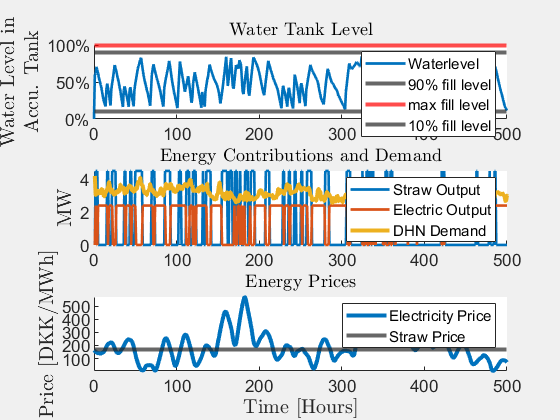

Elctricity Contribution round1: 914.4 MWh


Elctricity Cost round1: 133789.76 DKK


Straw Contribution round1: 558 MWh


Straw Cost round1: 96263.4816 DKK


Total energy production cost 1: 230053.2416DKK


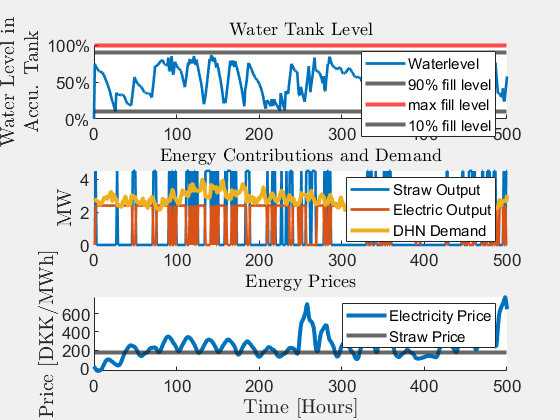

Elctricity Contribution round2: 878.4 MWh


Elctricity Cost round2: 146317.5 DKK


Straw Contribution round2: 481.5 MWh


Straw Cost round2: 83066.0688 DKK


Total energy production cost 2: 229383.5688DKK


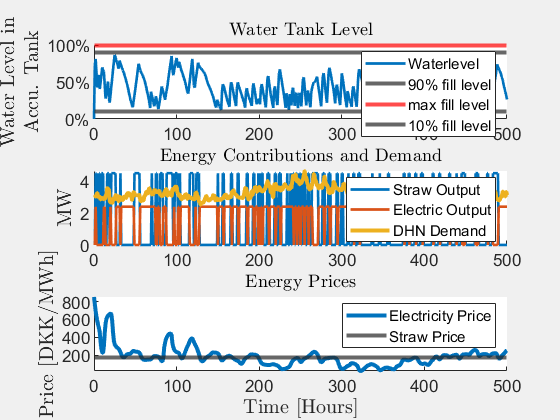

Elctricity Contribution round3: 928.8 MWh


Elctricity Cost round3: 127625.28 DKK


Straw Contribution round3: 679.5 MWh


Straw Cost round3: 117224.0784 DKK


Total energy production cost 3: 244849.3584DKK


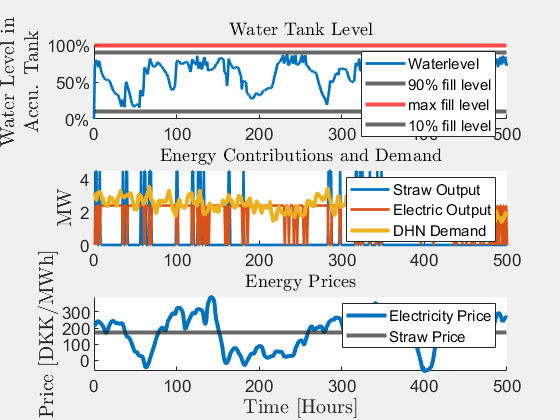

Elctricity Contribution round4: 1046.4 MWh


Elctricity Cost round4: 153989.02 DKK


Straw Contribution round4: 153 MWh


Straw Cost round4: 26394.8256 DKK


Total energy production cost 4: 180383.8456DKK


%Validation using 2021 data. This section can be run independantly by
%loading the appropriate agent and mode. Note the parameters defined in the
%first section must be run again.
close all;

actInfo = rlFiniteSetSpec({[0 0],[1 0],[0 1],[1 1]});
obsInfo = rlNumericSpec([28 1]);
mdl = "DHNV812163_genericExample";
env = rlSimulinkEnv(mdl,mdl+"/RL Agent",obsInfo, actInfo);

%Load pretrained agent. If a new agent was trained above, make sure to not
%load an agent, as otherwise the trained agent will be deleted.
load("agent0_NoStartUpPenalty_MVASignal.mat","agent")
%load("agent1_WithStartUpPenalty_MVASignal.mat","agent");

%Load data as in section one
T = readtable("HeatDemandData.csv");
T = table2array(T);
heatMax = max(T(1:2050));

T0 = readtable("ElSpot2020DK2.csv");
T1 = readtable("ElSpot2021DK2.CSV");
T0 = table2array(T0);
T1 = table2array(T1);

MeanT1 = movmean(T1(1:2050)-180,10); %2021
maxVal = max(MeanT1);

%temporary values used for testing multiple scenarios at once.
temp = 500+50;
temp2 = 1;
price = zeros(550,1);
round = 1;

%Running 4 different scenarios. Time step 1-500, 501-1000, 1001-1500 and
%1501-2000.
for x = 1:4
    
    heatConsumption = T(temp2:temp); 
    t = 1:550;
    heatDemand = timeseries(heatConsumption,t);
    heatDemand.Name = "Heat Demand";
    heatDemand.TimeInfo.Units = 'hours';
    
    %Creating appropriate data array depending on scenario.
    MeanT0 = movmean(T0(temp2:temp),10); %2020
    MeanT1 = movmean(T1(temp2:temp)-180,10); %2021
    Data2020 = MeanT0/maxVal;
    Data2021 = MeanT1/maxVal;
    
    %Set dataset
    HourAhead = Data2021;
    %turning arays into timeseries for simulink use
    t = 1:550;

    %setting price information for calculation of quantitative measures.
    if HourAhead == Data2020
        price = T0(temp2:temp);
    else
       price = T1(temp2:temp);
    end
    
    %Creating PLA features
    hourAhead = timeseries(HourAhead,t);
    hourAhead.Name = "Hour Ahead Price";
    hourAhead.TimeInfo.Units = 'hours';
      
    TP1 = HourAhead(2:end);
    TP2 = HourAhead(3:end);
    TP3 = HourAhead(4:end);
    TP4 = HourAhead(5:end);
    TP5 = HourAhead(6:end);
    TP6 = HourAhead(7:end);
    TP7 = HourAhead(8:end);
    TP8 = HourAhead(9:end);
    TP9 = HourAhead(10:end);
    TP10 = HourAhead(11:end);
    TP11 = HourAhead(12:end);
    TP12 = HourAhead(13:end);
    TP13 = HourAhead(14:end);
    TP14 = HourAhead(15:end);
    TP15 = HourAhead(16:end);
    TP16 = HourAhead(17:end);
    TP17 = HourAhead(18:end);
    TP18 = HourAhead(19:end);
    TP19 = HourAhead(20:end);
    TP20 = HourAhead(21:end);
    TP21 = HourAhead(22:end);
    TP22 = HourAhead(23:end);
    TP23 = HourAhead(24:end);
    
    t = 1:550-1;
    TS1 = timeseries(TP1,t);
    TS1.TimeInfo.Units = 'hours';
    
    t = 1:550-2;
    TS2 = timeseries(TP2,t);
    TS2.TimeInfo.Units = 'hours';
    
    t = 1:550-3;
    TS3 = timeseries(TP3,t);
    TS3.TimeInfo.Units = 'hours';
    
    t = 1:550-4;
    TS4 = timeseries(TP4,t);
    TS4.TimeInfo.Units = 'hours';
    
    t = 1:550-5;
    TS5 = timeseries(TP5,t);
    TS5.TimeInfo.Units = 'hours';
    
    t = 1:550-6;
    TS6 = timeseries(TP6,t);
    TS6.TimeInfo.Units = 'hours';
    
    t = 1:550-7;
    TS7 = timeseries(TP7,t);
    TS7.TimeInfo.Units = 'hours';
    
    t = 1:550-8;
    TS8 = timeseries(TP8,t);
    TS8.TimeInfo.Units = 'hours';
    
    t = 1:550-9;
    TS9 = timeseries(TP9,t);
    TS9.TimeInfo.Units = 'hours';
    
    t = 1:550-10;
    TS10 = timeseries(TP10,t);
    TS10.TimeInfo.Units = 'hours';
    
    t = 1:550-11;
    TS11 = timeseries(TP11,t);
    TS11.TimeInfo.Units = 'hours';
    
    t = 1:550-12;
    TS12 = timeseries(TP12,t);
    TS12.TimeInfo.Units = 'hours';
    
    t = 1:550-13;
    TS13 = timeseries(TP13,t);
    TS13.TimeInfo.Units = 'hours';
    
    t = 1:550-14;
    TS14 = timeseries(TP14,t);
    TS14.TimeInfo.Units = 'hours';
    
    t = 1:550-15;
    TS15 = timeseries(TP15,t);
    TS15.TimeInfo.Units = 'hours';
    
    t = 1:550-16;
    TS16 = timeseries(TP16,t);
    TS16.TimeInfo.Units = 'hours';
    
    t = 1:550-17;
    TS17 = timeseries(TP17,t);
    TS17.TimeInfo.Units = 'hours';
    
    t = 1:550-18;
    TS18 = timeseries(TP18,t);
    TS18.TimeInfo.Units = 'hours';
    
    t = 1:550-19;
    TS19 = timeseries(TP19,t);
    TS19.TimeInfo.Units = 'hours';
    
    t = 1:550-20;
    TS20 = timeseries(TP20,t);
    TS20.TimeInfo.Units = 'hours';
    
    t = 1:550-21;
    TS21 = timeseries(TP21,t);
    TS21.TimeInfo.Units = 'hours';
    
    t = 1:550-22;
    TS22 = timeseries(TP22,t);
    TS22.TimeInfo.Units = 'hours';
    
    t = 1:550-23;
    TS23 = timeseries(TP23,t);
    TS23.TimeInfo.Units = 'hours';

    %updating temporary values
    temp = temp+500;
    temp2 = temp2+500;

    %Extracing simulation information
    simout = sim(agent, env);
    
    %Extracting information from simulation output.
    obs = simout.Observation.obs1.Data;
    obsmat = squeeze(obs);
    obsmat = obsmat';
    t = simout.Observation.obs1.Time;
    
    demand = obsmat(:,2);
    waterLevel = obsmat(:,4);
    cost = obsmat(:,3);
    hourahead = obsmat(:,1);
    
    
    act = simout.Action.act1.Data;
    actmat = squeeze(act);
    actmat = actmat';
    actmat = [0 0 ; actmat];
    
    

    set(0,'DefaultTextInterpreter','latex');
    DefFontSize = 15; % for a column in paper use 20
    set(0,'DefaultAxesFontSize',DefFontSize);
    set(0,'DefaultLineLineWidth', 1);
    
    gcf = figure();
    set(gcf,'Visible','on')
    
    subplot(3,1,1)
    hold on;
    plot(t,waterLevel*100, 'LineWidth',2)
    ytickformat('percentage')
    yline(90,'LineWidth',3) %90% fill level
    yline(100,'LineWidth',3,'Color', [1,0,0]) %max fill level
    yline(10,'LineWidth',3)% 10% fill level
    legend('Waterlevel','90% fill level', 'max fill level', '10% fill level','location','northeast')
    title({'Water Tank Level'})
    %xlabel({'Time [Hours]'}, 'FontSize',DefFontSize,'Interpreter','latex');
    ylabel({'Water Level in','Accu. Tank'}, 'FontSize',DefFontSize,'Interpreter','latex');
    axis([0 500 -inf inf]);
    
    subplot(3,1,2)
    hold on;
    plot(actmat(:,2)*4.5,'LineWidth',2)
    plot(actmat(:,1)*2.4,'LineWidth',2)
    plot(heatConsumption*200/1000,'LineWidth',3)
    legend('Straw Output','Electric Output','DHN Demand','location','northeast')
    axis([0 500 -inf inf]);
    title('Energy Contributions and Demand')
    %xlabel({'Time [Hours]'}, 'FontSize',DefFontSize,'Interpreter','latex');
    ylabel({'MW'}, 'FontSize',DefFontSize,'Interpreter','latex');
    
    subplot(3,1,3)
    hold on;
    title('Energy Prices')
    plot(t,hourahead*maxVal,'LineWidth',3)
    yline(P_h*maxVal,'LineWidth',3);
    legend('Electricity Price','Straw Price','location','northeast')
    xlabel({'Time [Hours]'}, 'FontSize',DefFontSize,'Interpreter','latex');
    ylabel({'Price [DKK/MWh]'}, 'FontSize',DefFontSize,'Interpreter','latex');
    axis([0 500 -inf inf]);
    

    %Calculating performance metrics.
    strawContribution = sum(actmat(:,2)*4.5);
    StrawCosttotal = strawContribution*P_h*maxVal;
    ElContribution = sum(actmat(:,1)*2.4);
    Elcosttotal = 0;
    for temp3 = 1:500
         temp4 = actmat(temp3,1)*(price(temp3));
         Elcosttotal = Elcosttotal + temp4;
    end
    
    CostTot = Elcosttotal + StrawCosttotal;

    disp(['Elctricity Contribution round', num2str(round),': ', num2str(ElContribution), ' MWh'])
    disp(['Elctricity Cost round', num2str(round),': ', num2str(Elcosttotal), ' DKK'])
    disp(['Straw Contribution round', num2str(round),': ',num2str(strawContribution), ' MWh'])
    disp(['Straw Cost round', num2str(round),': ', num2str(StrawCosttotal), ' DKK'])
    disp(['Total energy production cost ',num2str(round),': ', num2str(CostTot), 'DKK'])
    
    %For printing figures
    w = 40; %document width [cm]
    h = 28;  %document height [cm]
    set(gcf,'paperunits','centimeters','Paperposition',[0 0 w h])
    set(gcf,'PaperSize',[w h]); %set the paper size     
    %activaing the below line will save the plot. Make sure to change the
    %name between running different agents.
    %print(gcf,['Agent0PenaltyFFTSignal',num2str(round)],'-dpdf');

    round = round + 1;
end